clc
clear
clf

%% Model Parameters
m_r = 0.082;
m_w = 0.002;
l_r = 0.35;
m_p = 0.084;
COMp = (m_r*(l_r/2)+ m_w*l_r)/(m_r + m_w);
l= COMp;
I1 = (1/3)*m_p*l^2 ;  % I med l

%% Constants
M = 0.5;
m_p = 0.084;
b_c = 5;
b_p = 0.0012;
g = 9.82;
l = 0.1792;
I = (1/3)*m_p*(0.35^2);  % I med 2l

% State space model
A = [0 1 0 0; 0 -b_c/(M+(m_p*I)/(m_p*l^2+I)) (m_p^2*l^2*g)/(M*(m_p*l^2+I)+m_p*I) (m_p*l*b_p)/(M*(m_p*l^2+I)+m_p*I); 0 0 0 1; 0 -(m_p*l*b_c)/(I*(M+m_p)+M*m_p*l^2) (m_p*g*l*(M+m_p))/(I*(M+m_p)+M*m_p*l^2) -(b_p*(M+m_p))/(I*(M+m_p)+M*m_p*l^2)]

A =          0    1.0000         0         0
         0   -9.1404    0.6638    0.0054
         0         0         0    1.0000
         0  -22.4545   25.7547   -0.2091


B = [0; 1/(M+(m_p*I)/(m_p*l^2+I)); 0; (m_p*l)/(I*(M+m_p)+M*m_p*l^2)]

B =          0
    1.8281
         0
    4.4909


C = [1 0 0 0; 0 0 1 0]

C =      1     0     0     0
     0     0     1     0


D = [0; 0];

% Converting state space to transfer functions
%rank = rank(ctrb(A,B));
s = tf('s');
sys = ss(A,B,C,D);
tfCart = minreal(tf(sys(1)))

tfCart =
 
       1.828 s^2 + 0.4064 s - 44.1
  -------------------------------------
  s^4 + 9.349 s^3 - 23.72 s^2 - 220.5 s
 
Continuous-time transfer function.



tfPendulum = minreal(tf(sys(2)))

tfPendulum =
 
         4.491 s - 1.058e-15
  ---------------------------------
  s^3 + 9.349 s^2 - 23.72 s - 220.5
 
Continuous-time transfer function.



% Controller Variables
%Pendlum
Kp = 366.069991564719;
Ti = 3701.82722683723;
Td = 8.8851655469107;
N = 1126.11038715991;

%Cart
Kpc = -843.8063316859;
Tic = -200.862441767316;
Tdc = 59.7349659468271;
Nc = 8.95379916090364;

% PID Controller Cart
%KpidC = 1 + 1/(Tic*s) + (Tdc*s)/(1+s*(Tdc/Nc));
KpidC = pid(Kpc, Tic, Tdc, Nc)

KpidC =
 
             1            s    
  Kp + Ki * --- + Kd * --------
             s          Tf*s+1 

  with Kp = -844, Ki = -201, Kd = 59.7, Tf = 8.95
 
Continuous-time PIDF controller in parallel form.



%KpidC = Kpc + Tic * 1/s + Tdc * s/((Tdc/Nc)*s+1);

% PID Controller Pendulum
%KpidP = 1 + 1/(Ti*s) + (Td*s)/(1+s*(Td/N));
KpidP = pid(Kp, Ti, Td, N)

KpidP =
 
             1            s    
  Kp + Ki * --- + Kd * --------
             s          Tf*s+1 

  with Kp = 366, Ki = 3.7e+03, Kd = 8.89, Tf = 1.13e+03
 
Continuous-time PIDF controller in parallel form.



%KpidP = Kp + Ti * 1/s + Td * s/((Td/N)*s+1);

% Pole zero maps of the different transfer functions
[p,z] = pzmap(tfPendulum)

p =     4.8612
   -9.3697
   -4.8411


z = 2.3551e-16

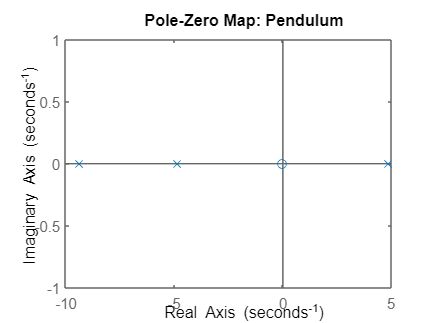

pzplot(tfPendulum)
title('Pole-Zero Map: Pendulum')

[p,z] = pzmap(tfCart)

p =          0
    4.8612
   -9.3697
   -4.8411


z =    -5.0240
    4.8017


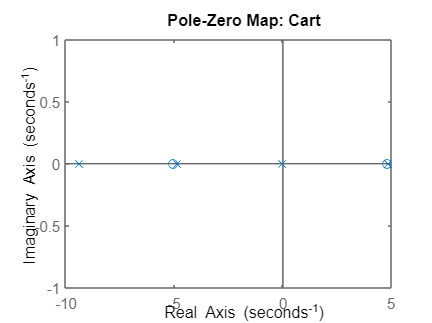

pzplot(tfCart)
title('Pole-Zero Map: Cart')

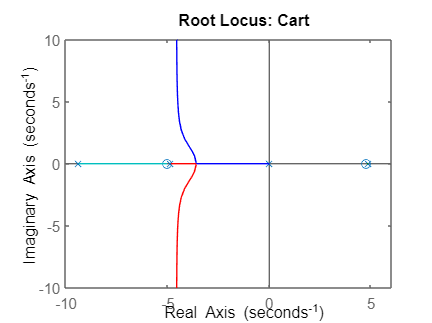


%% Root locus plots of the transferfunctions
rlocus(tfCart)
title('Root Locus: Cart')

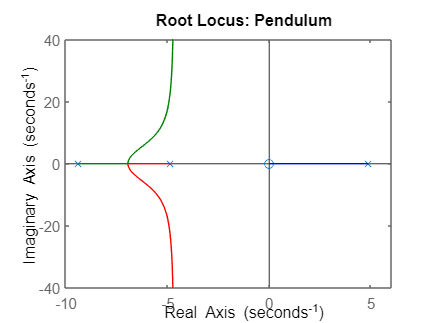

rlocus(tfPendulum)
title('Root Locus: Pendulum')

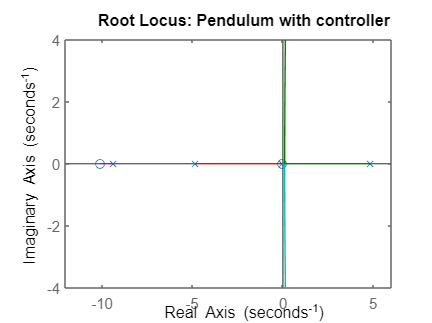

%% Root locus of the transferfunctions with controller
rlocus(KpidP * tfPendulum)
title('Root Locus: Pendulum with controller')

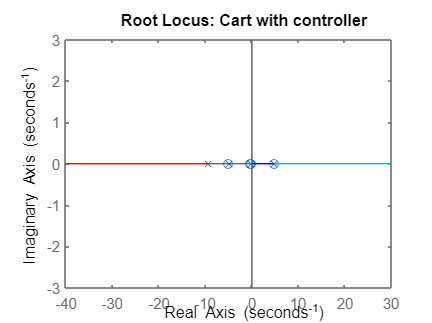

rlocus(KpidC * tfCart)
title('Root Locus: Cart with controller')

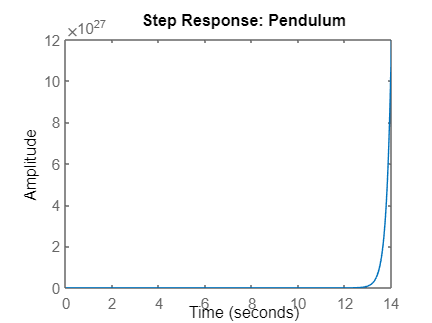


%% Step response for the system
step(tfPendulum)
title('Step Response: Pendulum')

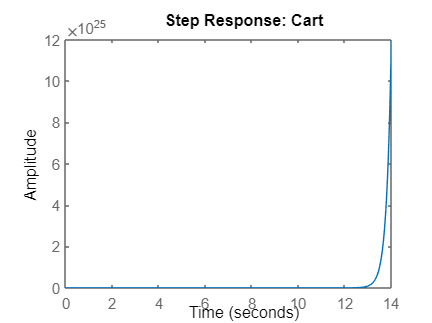

step(tfCart)
title('Step Response: Cart')

%% Step response for the system with controller
%K = Kp * KpidP;
%G1 = (K * tfPendulum) / (1 + K * tfPendulum)
G1 = (KpidP * tfPendulum) / (1 + KpidP * tfPendulum)

G1 =
 
            1644 s^8 + 3.2e04 s^7 + 1.165e05 s^6 - 7.567e05 s^5 - 3.667e06 s^4 - 6511 s^3 - 2.891 s^2 + 6.808e-16 s
  ---------------------------------------------------------------------------------------------------------------------------
  s^10 + 18.7 s^9 + 1684 s^8 + 3.111e04 s^7 + 1.129e05 s^6 - 7.462e05 s^5 - 3.618e06 s^4 - 6425 s^3 - 2.852 s^2 + 6.808e-16 s
 
Continuous-time transfer function.



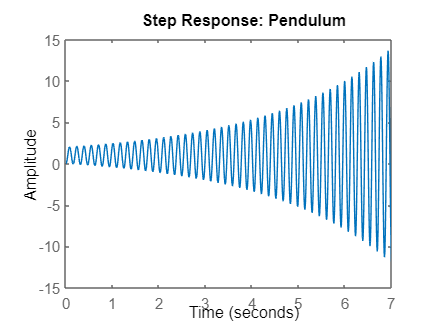

step(G1)
title('Step Response: Pendulum')

%K2 = Kpc * KpidC;
%G2 = (K2 * tfCart) / (1 + K2 * tfCart)
G2 = (KpidC * tfCart) / (1 + KpidC * tfCart)

G2 =
 
                                                                                                                                       
       -1530 s^10 - 1.536e04 s^9 + 6.314e04 s^8 + 7.222e05 s^7 - 4.756e05 s^6 - 8.466e06 s^5 - 3.83e06 s^4 - 5.41e05 s^3 - 2.436e04 s^2
                                                                                                                                       
  -------------------------------------------------------------------------------------------------------------------------------------------
                                                                                                                                             
  s^12 + 18.92 s^11 - 1486 s^10 - 1.623e04 s^9 + 5.938e04 s^8 + 7.319e05 s^7 - 4.247e05 s^6 - 8.455e06 s^5 - 3.829e06 s^4 - 5.41e05 s^3      
                                                                                                                                             
                 

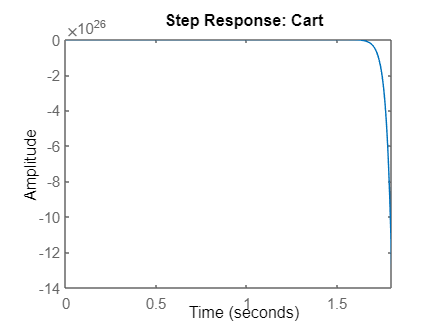

step(G2)
title('Step Response: Cart')

Cascade control:

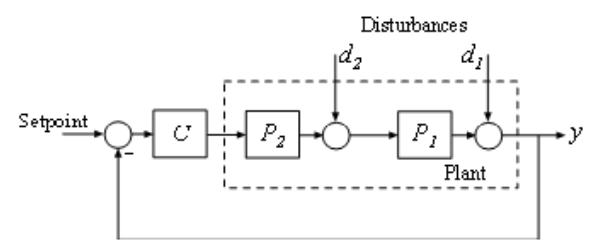

G = tfCart * tfPendulum;
Ccasc = pidstd(Kp,Ti,Td,N);
Ccasc = pidtune(G,Ccasc,0.2);

Ccasc

Ccasc =
 
             1      1              s      
  Kp * (1 + ---- * --- + Td * ------------)
             Ti     s          (Td/N)*s+1 

  with Kp = -6.46, Ti = 857, Td = 190, N = 4.35e+03
 
Continuous-time PIDF controller in standard form




% First parameter is P2.
C2 = pidtune(tfCart,pidstd(Kp,Ti,Td,N),2);
C2

C2 =
 
             1      1              s      
  Kp * (1 + ---- * --- + Td * ------------)
             Ti     s          (Td/N)*s+1 

  with Kp = -0.269, Ti = 85.7, Td = 19, N = 4.35e+03
 
Continuous-time PIDF controller in standard form




% Makes the inner closed loop. Second parameter is feedback gain
clsys = feedback(tfCart*C2,1); 

% Plant seen by the outer loop controller C1 is clsys*P1
C1 = pidtune(clsys*tfPendulum,pidstd(Kp,Ti,Td,N),0.2);

C1

C1 =
 
             1      1              s      
  Kp * (1 + ---- * --- + Td * ------------)
             Ti     s          (Td/N)*s+1 

  with Kp = 1.81, Ti = 857, Td = 190, N = 4.35e+03
 
Continuous-time PIDF controller in standard form



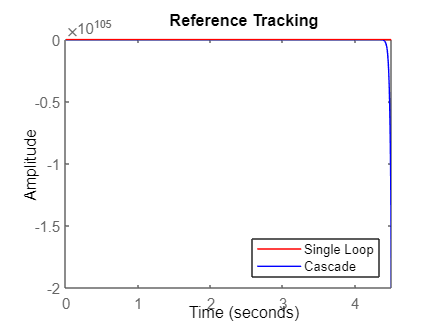


% single loop system for reference tracking 
sys1 = feedback(G*Ccasc,1);
sys1.Name = 'Single Loop';

% cascade system for reference tracking
sys2 = feedback(clsys*tfPendulum*C1,1); 
sys2.Name = 'Cascade';

% plot step response
figure;
step(sys1,'r',sys2,'b')
legend('show','location','southeast')
title('Reference Tracking')

modern controller

%% controlability & observability
% controllability
controlMatrix = ctrb(A,B);
rank(controlMatrix);
determindCon= det(controlMatrix);

% observability
observeMatrix = obsv(A,C);
rank(observeMatrix);
%determindObs= det(observeMatrix);

%% Integral action
Ae = [A(1,:) 0 0; A(2,:) 0 0; A(3,:) 0 0 ; A(4,:) 0 0; C(1,:) 0 0; C(2,:) 0 0]

Ae =          0    1.0000         0         0         0         0
         0   -9.1404    0.6638    0.0054         0         0
         0         0         0    1.0000         0         0
         0  -22.4545   25.7547   -0.2091         0         0
    1.0000         0         0         0         0         0
         0         0    1.0000         0         0         0


Be = [B; 0 ;0]

Be =          0
    1.8281
         0
    4.4909
         0
         0


Ce = [C(1,:) 0 0; C(2,:) 0 0]

Ce =      1     0     0     0     0     0
     0     0     1     0     0     0


%%  feedback gain F og observer L
Ts= 1;
Alpha= 1;
Sigma= -log(Alpha/100)/Ts

Sigma = 4.6052

p_1 = [-6; -7; -8; -11; -12; -13];
F = -place(Ae,Be,p_1);

Error using place
The "place" command could not place the poles at the specified locations. Probable causes include:
* (A,B) is nearly uncontrollable
* The specified locations are too close to each other.


p_2 = [-6; -7; -8; -9]  
P_obs= p_2*5        
L= -place(A',C',P_obs)'